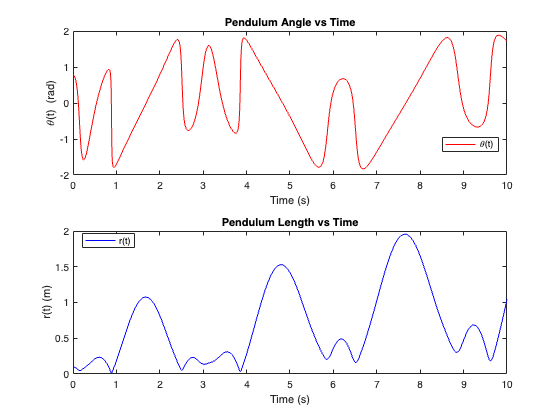

% Define parameters
m = 1;        % kg
k = 2;        % N/m
l0 = 0.1;     % m
g = 9.81;     % m/s^2

% Initial conditions
theta0 = pi/4;  % rad
dtheta0 = 0;    % rad/s
r0 = l0;        % m
dr0 = 0;        % m/s

% Time span
tspan = [0 10]; % seconds

% Initial state vector [r, dr, theta, dtheta]
y0 = [r0; dr0; theta0; dtheta0];

% Solve using ode45
[t, y] = ode45(@(t, y) equations_of_motion(t, y, m, k, l0, g), tspan, y0);

% Plot results
figure;
subplot(2,1,1);
plot(t, y(:, 3), 'r'); % theta(t)
xlabel('Time (s)');
ylabel('\theta(t) (rad)');
title('Pendulum Angle vs Time');
legend('\theta(t)', 'Location', 'best');

subplot(2,1,2);
plot(t, y(:, 1), 'b'); % r(t)
xlabel('Time (s)');
ylabel('r(t) (m)');
title('Pendulum Length vs Time');
legend('r(t)', 'Location', 'best');

function dydt = equations_of_motion(~, y, m, k, l0, g)
    r = y(1);      % length
    dr = y(2);     % rate of change of length
    theta = y(3);  % angle
    dtheta = y(4); % rate of change of angle

    % Equations of motion
    d2r = r * dtheta^2 - g * cos(theta) - (k/m) * (r - l0);
    d2theta = (-2 * dr * dtheta - g * sin(theta)) / r;

    % Return derivatives
    dydt = [dr; d2r; dtheta; d2theta];
end